# CIFI V. Problema: Digitt. Materia: Metodos de Inteligencia Artificial

## Cargamos datos

Cargamos los datos ya estandarizados

load Digitt.mat
data

data =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -0.5972   -0.1960    0.9629    0.4280    0.3834   -0.5393    0.6063   -0.5972    0.6063   -0.6774   -0.3298   -0.5749   -0.1069   -0.8424   -0.7101   -0.8201   -0.3966   -0.3298   -0.1515   -0.5081   -0.8201   -0.1515    1.0074   -0.5883    0.2943    0.1605    0.0714   -0.3743   -0.6864   -0.6864   -0.3743    2.5230   -0.4412   -0.5081    0.5171   -0.5081   -0.0178   -0.5303    0.2943    0.6954   -0.5972   -0.4412    0.2943    0.1516   -0.1069    2.5230    4.3059   -0.1515   -0.1960  

## Income

Exploración de la variable de ingreso

bins = 0:15000:300000

bins =            0       15000       30000       45000       60000       75000       90000      105000      120000      135000      150000      165000      180000      195000      210000      225000      240000      255000      270000      285000      300000


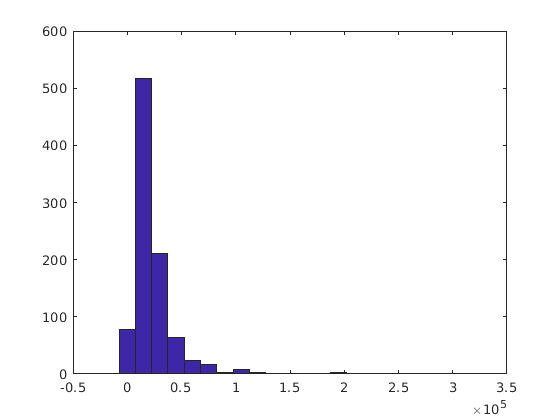

hist(income,bins)

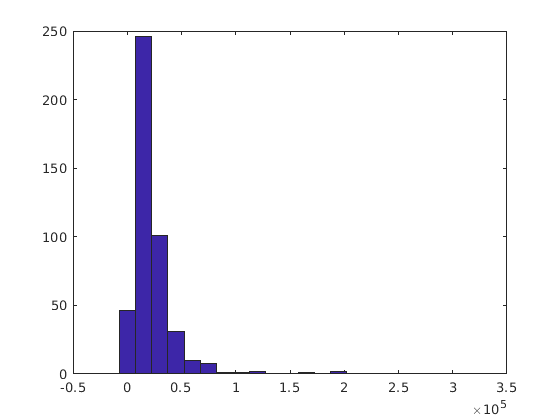

hist(income(Y==1),bins)

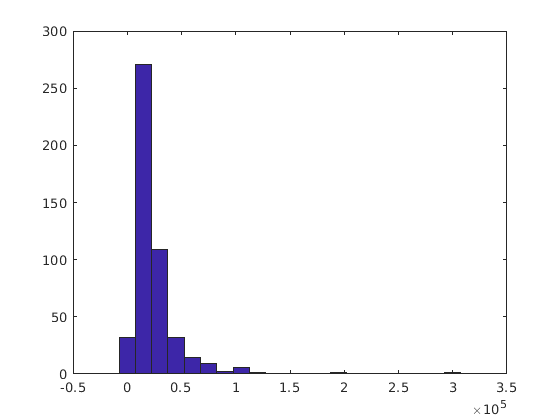

hist(income(Y==0),bins)

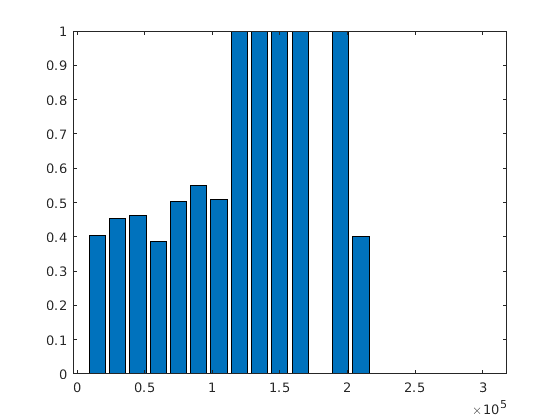

indx_income = bins;
pct_income = zeros(size(indx_income,2)-1,1);
for i=1:size(indx_income,2)-1
    tmp = income(income>indx_income(i));
    Y_ = Y(income>indx_income(i));
    tmp = tmp(tmp<indx_income(i+1));
    Y_ = Y_(tmp<indx_income(i+1));
    if sum(size(tmp))>0
        pct_income(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_income(2:end),pct_income)

## Age

Exploración de la variable edad. Debido a que las graficas de prestamos aceptados y negados se parece demasiado a la grafica de prestamos solicitados podemos concluir que la edad no es un factor determinante en el prestamo. 

bins = 18:5:68

bins =     18    23    28    33    38    43    48    53    58    63    68


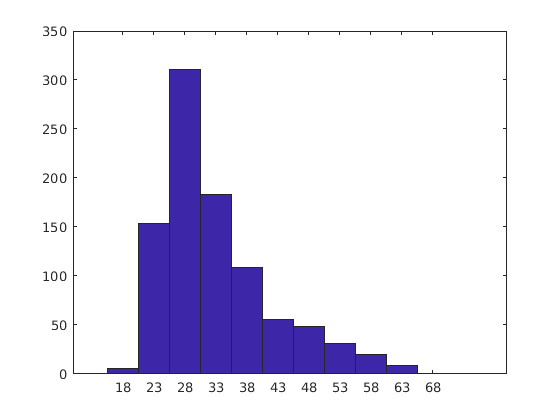

hist(age, bins)

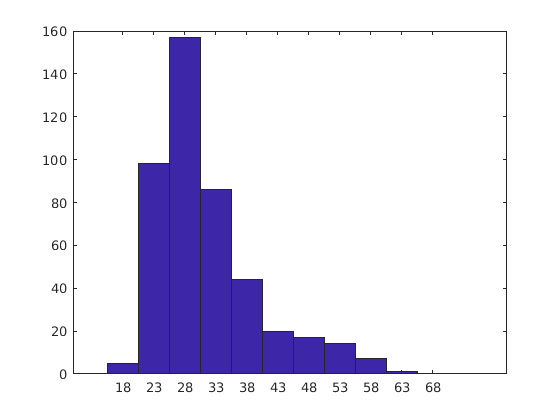

hist(age(Y==1), bins)

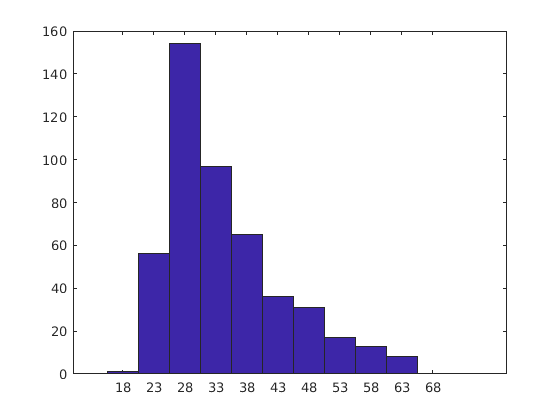

hist(age(Y==0), bins)

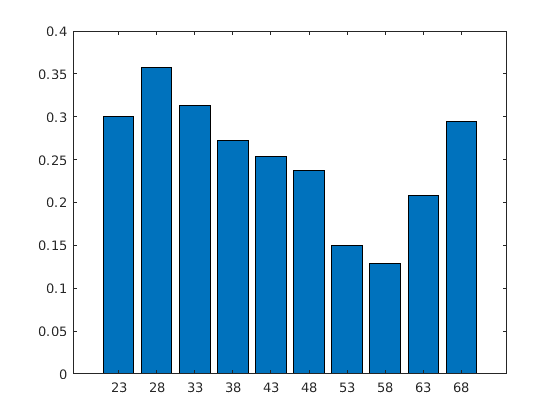

indx_age = bins;
pct_age = zeros(size(indx_age,2)-1,1);
for i=1:size(indx_age,2)-1
    tmp = age(age>indx_age(i));
    Y_ = Y(age>indx_age(i));
    tmp = tmp(tmp<indx_age(i+1));
    Y_ = Y_(tmp<indx_age(i+1));
    if sum(size(tmp))>0
        pct_age(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_age(2:end),pct_age)

## Score

Exploración de variable 'score'. Se decidio no utilizar la variable Icc debido a que otorga 'la misma' información que 'score' pero desde una diferente fuente de datos. Es importante notar que esta variable es determinante para el prestamo ya que a mayor cantidad de score mayor probabilidad de que se otorgue el prestamo (cerca de un 70% en score altos en comparación con un 30% en score bajos)

bins = 622:7:727

bins =    622   629   636   643   650   657   664   671   678   685   692   699   706   713   720   727


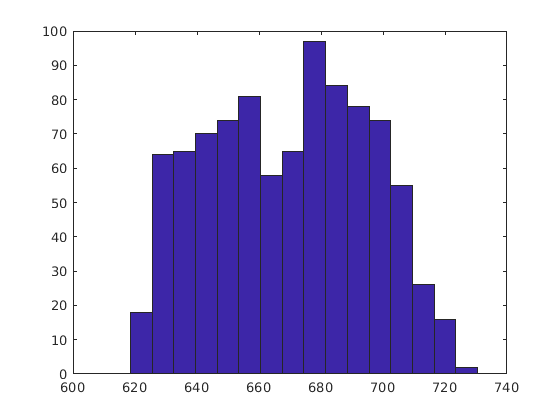

hist(score, bins)

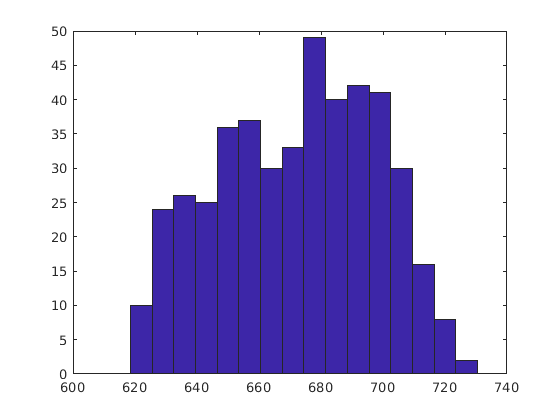

hist(score(Y==1), bins)

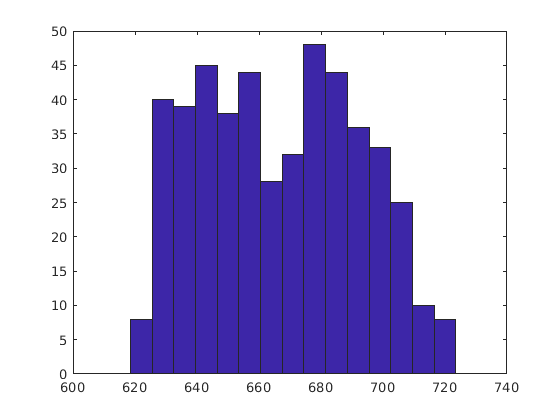

hist(score(Y==0), bins)

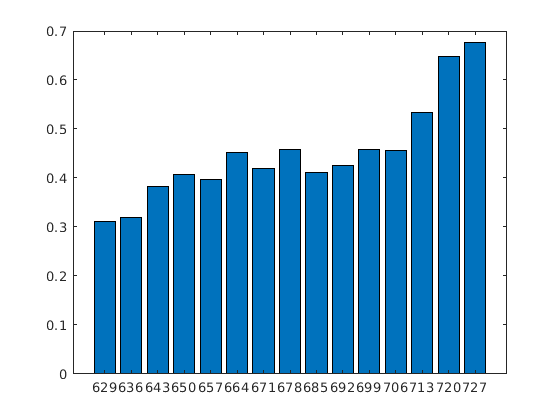

indx_score = bins;
pct_score = zeros(size(indx_score,2)-1,1);
for i=1:size(indx_score,2)-1
    tmp = score(score>indx_score(i));
    Y_ = Y(score>indx_score(i));
    tmp = tmp(tmp<indx_score(i+1));
    Y_ = Y_(tmp<indx_score(i+1));
    if sum(size(tmp))>0
        pct_score(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_score(2:end),pct_score)

## Total Debt

Exploración del total de la deuda. No se pueden generar conclusiones en este punto, más adelante se comprueba que esta variable es un factor determinate para el prestamo. 

bins = 0:20000:500000

bins =            0       20000       40000       60000       80000      100000      120000      140000      160000      180000      200000      220000      240000      260000      280000      300000      320000      340000      360000      380000      400000      420000      440000      460000      480000      500000


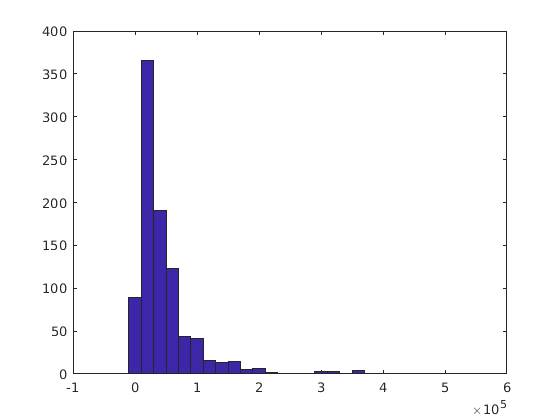

hist(total_debt, bins)

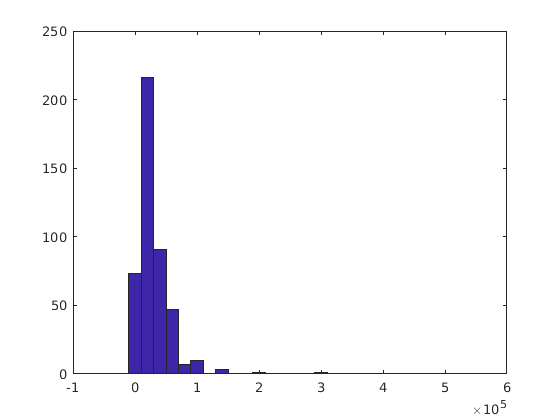

hist(total_debt(Y==1), bins)

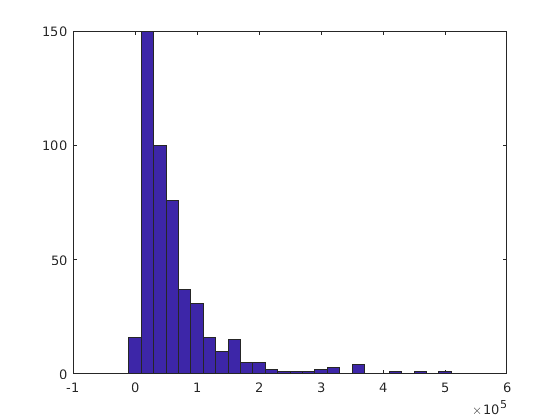

hist(total_debt(Y==0), bins)

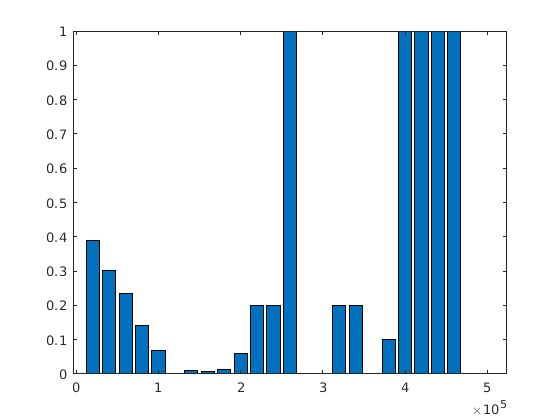

indx_total_debt = bins;
pct_total_debt = zeros(size(indx_total_debt,2)-1,1);
for i=1:size(indx_total_debt,2)-1
    tmp = total_debt(total_debt>indx_total_debt(i));
    Y_ = Y(total_debt>indx_total_debt(i));
    tmp = tmp(tmp<indx_total_debt(i+1));
    Y_ = Y_(tmp<indx_total_debt(i+1));
    if sum(size(tmp))>0
        pct_total_debt(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_total_debt(2:end),pct_total_debt)

## Amount to be lend

Exploración de la cantidad de dinero que se pide prestado. 

bins = 0:20000:500000

bins =            0       20000       40000       60000       80000      100000      120000      140000      160000      180000      200000      220000      240000      260000      280000      300000      320000      340000      360000      380000      400000      420000      440000      460000      480000      500000


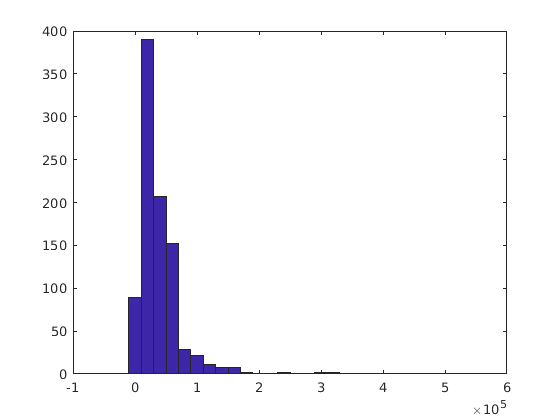

hist(amount_to_be_lend, bins)

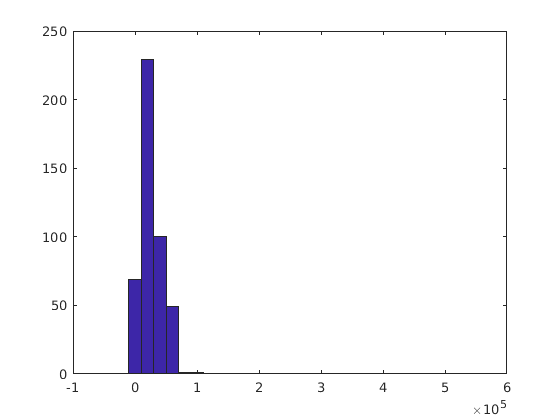

hist(amount_to_be_lend(Y==1), bins)

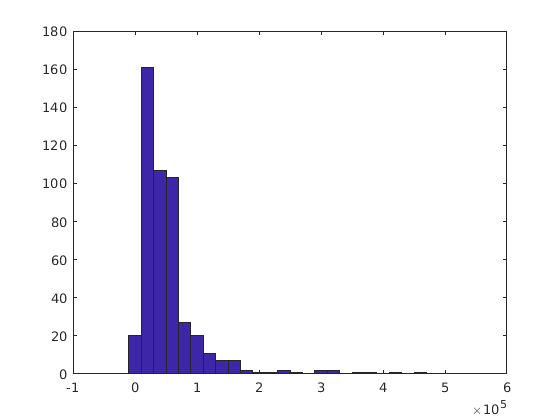

hist(amount_to_be_lend(Y==0), bins)

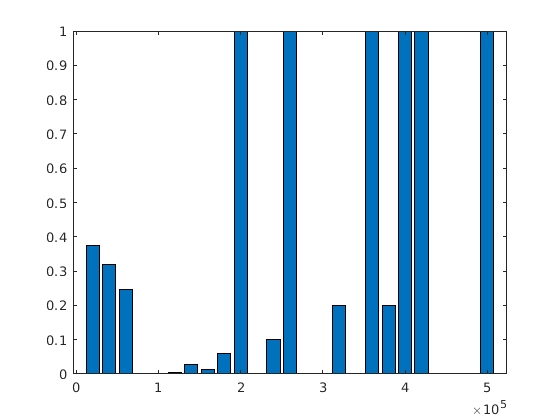

indx_amount_to_be_lend = bins;
pct_amount_to_be_lend = zeros(size(indx_amount_to_be_lend,2)-1,1);
for i=1:size(indx_amount_to_be_lend,2)-1
    tmp = amount_to_be_lend(amount_to_be_lend>indx_amount_to_be_lend(i));
    Y_ = Y(amount_to_be_lend>indx_amount_to_be_lend(i));
    tmp = tmp(tmp<indx_amount_to_be_lend(i+1));
    Y_ = Y_(tmp<indx_amount_to_be_lend(i+1));
    if sum(size(tmp))>0
        pct_amount_to_be_lend(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_amount_to_be_lend(2:end),pct_amount_to_be_lend)

## Variables Categoricas

## Genero

Se puede apreciar que es un poco más probable que se le preste dinero a un hombre que a una mujer, la diferencia es cercana al 3%. 

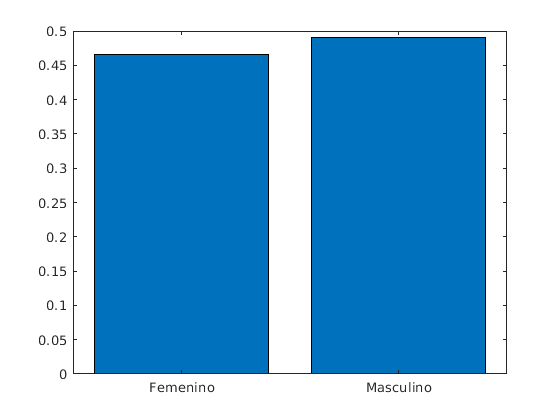

bar(categorical({'Femenino','Masculino'}),sum(gender(Y==1,:),1)./sum(gender(:,:),1))

## Tipo de vivienda

Se puede apreciar que las personas que rentan casa tienen un 50% más de probabilidad de recibir un prestamo que las personas que viven en casa de sus familiares o que tienen una casa propia. 

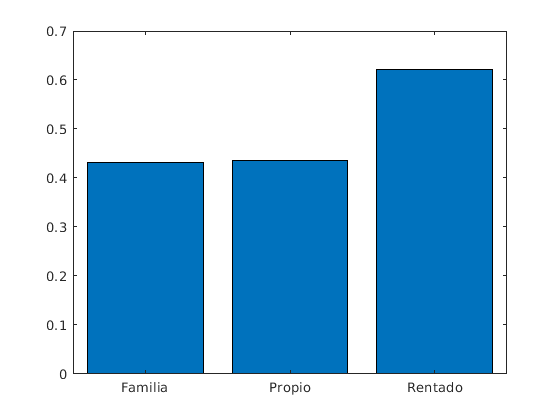


bar(categorical({'Familia','Propio','Rentado'}),sum(housing_type(Y==1,:),1)./sum(housing_type(:,:),1))

## Nivel de estudios.

No parece ser un factor determinante en el prestamo. A pesar de esto, las personas con posgrado reciben mas prestamos que la gente con preparatoria, y estos ultimos reciben aún más que aquellos con licenciatura. 

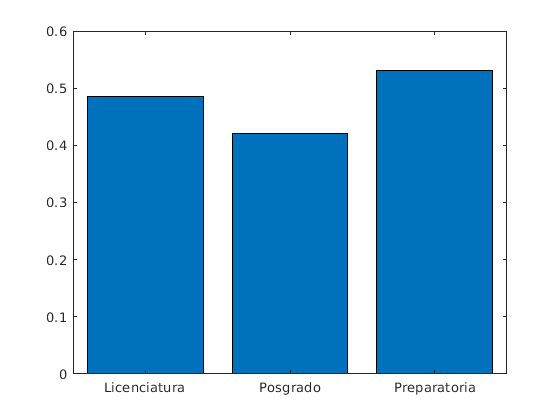


bar(categorical({'Licenciatura','Posgrado','Preparatoria'}),sum(level_of_studies(Y==1,:),1)./sum(level_of_studies(:,:),1))

## Estado civil

Para este caso en especifico, parece que la variable 'viudo' tiene mucho peso debido a que a presenta una probabilidad del 0% de que se les preste. (en este caso se presenta un sesgo, ya que solamente se tiene datos de 5 viudos y en ninguno de los casos se otorga un prestamo, aunque no necesariamente se deba al estado civil presentado). Se puede notar también que a las personas con mayor tasa de prestamos aceptados la consiguieron en union libre, mientras que la menor tasa la obtuivieron los separados. 

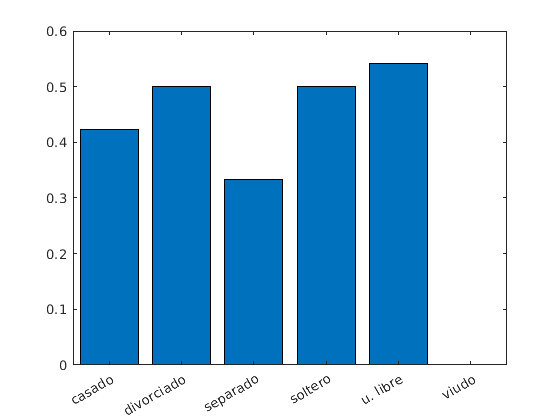


bar(categorical({'casado','divorciado' ,'separado' ,'soltero', 'u. libre','viudo'}),sum(marital_status(Y==1,:),1)./sum(marital_status(:,:),1))

## Los datos y su estructura (datos ya estandarizados)

Se proponen 4 selecciones de datos distintas para ajuste de modelos; La primera toma únicamente los valores cuantitativos de la base de datos, La segundo toma únicamente los valores 'cualitativos' (aquellos que presentan una clasificación sin un orden de importancia; genero, tipo de casa, ...) La tercera toma una mezcla de variables cuantitativas y cualitativas, Y la cuarta toma todas las variables cuantitativas y cualitativas que se decidió tomar en un inicio. 

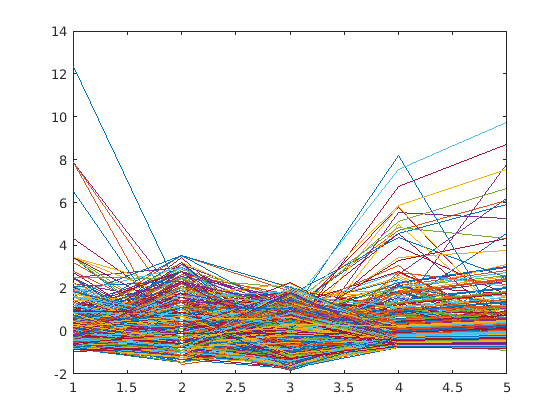

% income age score total_debt amount_to_be_lend (Cuantitativos)
plot(X1')

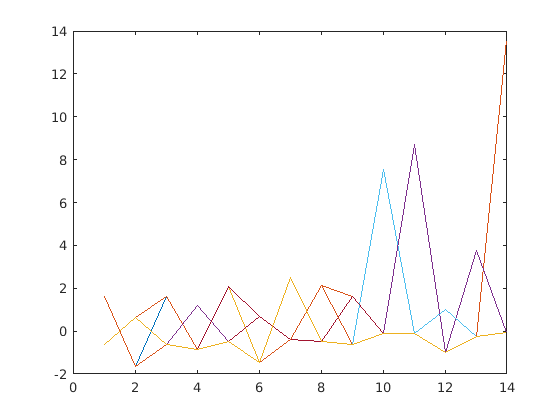

% gender housing_type level_of_studies marital_status (Cualitativos)
plot(X2')

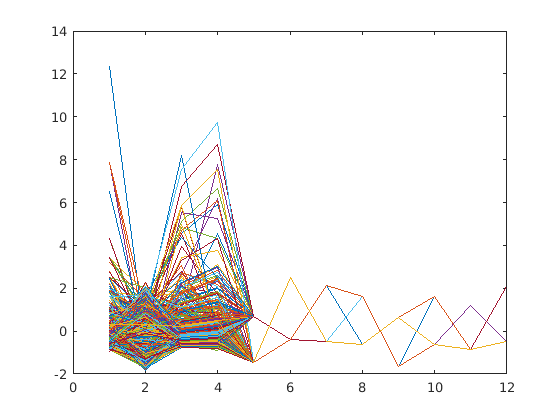

% income score total_debt amount_to_be_lend level_of_studies gender housing_type
% (Cuantitativos y Cualitativos)
plot(X3')

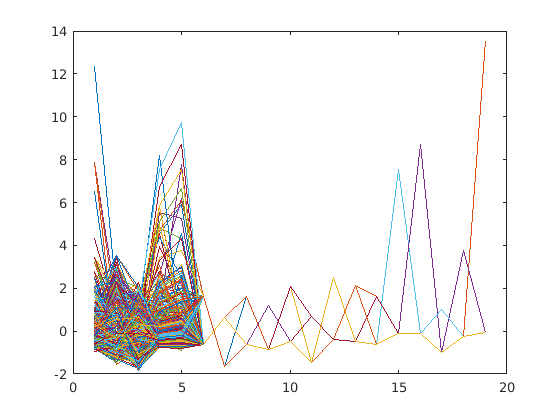

% income age score total_debt amount_to_be_lend gender housing_type level_of_studies marital_status
% (Cuantitativos y cualitativos)
plot(X4')

## Importancia de los pesos del perceptron

###     Como interpretar las siguientes graficas:

En los siguientes graficos se presentan graficos de dispersión de los pesos que se le otorgan a cada variable. En cada una de las selecciones de datos mencionadas en el apartado anterior se ajustaron 2 modelos; el primero de ellos lineal y el segundo de ellos cuadrático. El resultado de un modelo cuadrático sería el siguiente: 

[~,ord] = func_polinomio(1:5,2)

ord =      0     1     0     0     0     0     1     1     1     1     0     0     0     0     0     0     2     0     0     0     0
     0     0     1     0     0     0     1     0     0     0     1     1     1     0     0     0     0     2     0     0     0
     0     0     0     1     0     0     0     1     0     0     1     0     0     1     1     0     0     0     2     0     0
     0     0     0     0     1     0     0     0     1     0     0     1     0     1     0     1     0     0     0     2     0
     0     0     0     0     0     1     0     0     0     1     0     0     1     0     1     1     0     0     0     0     2


Las filas representan cada una de las variables y el número que las acompaña representa la potencia a la cual es elevada cada una de esas variables para generar la columna. Para la primer columna, se elevaron todas las variables a la potencia 0. para la 2da columna se toma únicamente la primer variable, a partir de la columna 7 se toman las combinaciones lineales de las variables, y apartir de la columna 17 se toman las variables al cuadrado. Se sigue el mismo patron para cualquier cantidad de variables. Mientras más cercano este un punto al 0 menos importancia tendrá este para el modelo, sin embargo, si está demasiado lejos del 0 se puede llegar a un sobre-ajuste (en ninguno de los modelos presentados se llegó a un sobre-ajuste).

Wperceptron.m1g1

ans =    -0.3045
    0.5617
   -0.1966
    0.2833
   -0.5939
   -1.4492


En el grado 1; los pesos de mayor relevancia son el 2, 5 y 6. Siendo estos respectivamente income en grado 1, total debt en grado 1 y amount to be lend en grado 1.

Wperceptron.m1g2

ans =    -0.1806
    1.0642
   -0.2428
    0.2684
   -0.9917
   -1.2829
   -0.2165
   -0.1475
   -0.0581
    0.3530


Para la misma seleccion de datos, con un modelo de grado 2 se obtiene que los pesos de mayor importancia son 6, 2, 21, 5, 16 y 10. siendo las siguientes: 

- amount_to_be_lend^1

- income^1

- amount_to_be_lend^2

- total_debt^1

- amount_to_be_lend^1 * total_debt^1

- income^1 * amount_to_be_lend^1

A continuación se presenta el gráfico de los modelos de grado 1 y 2 simultaneamente. 

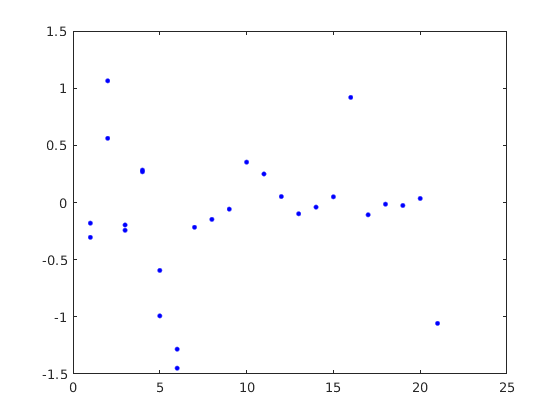

% income age score total_debt amount_to_be_lend
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',1,k));
    hold on 
end
hold off

Se presenta el grafico de dispersión con las variables cualitativas en grado 1 y 2.

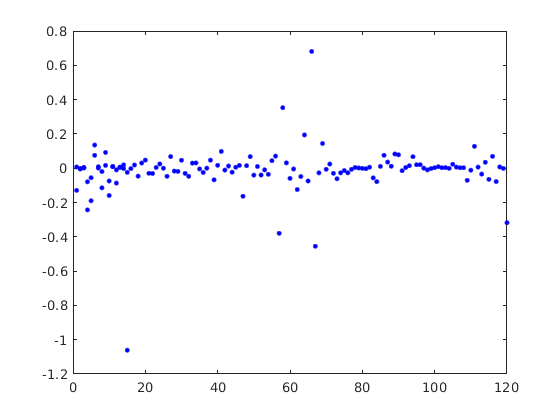

% gender housing_type level_of_studies marital_status
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',2,k));
    hold on 
end
hold off

Se presenta la tercer sleccion de datos con variables cualitativas y cuantitativas en grado 1 y 2. 

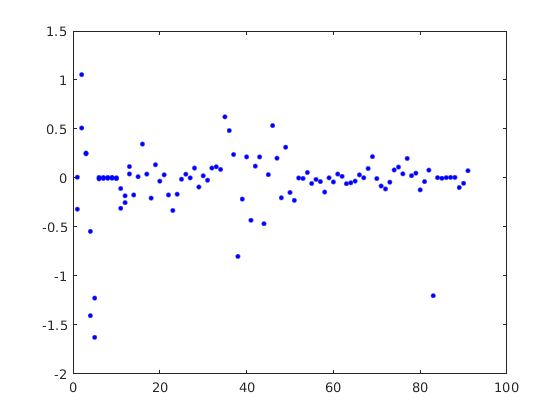

% income score total_debt amount_to_be_lend level_of_studies gender housing_type
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',3,k));
    hold on 
end
hold off

Se presenta la selección de datos con todas las variables selectas en grado 1 y 2. 

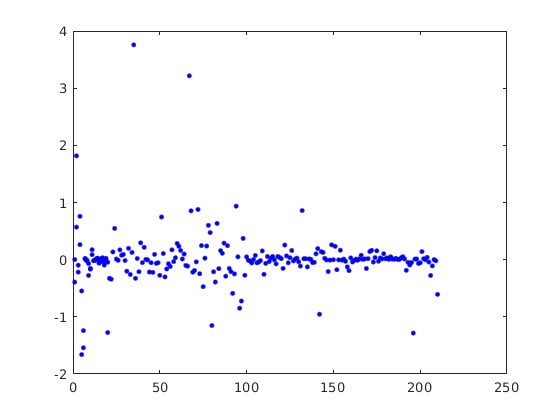

% income age score total_debt amount_to_be_lend gender housing_type level_of_studies marital_status
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',4,k));
    hold on 
end
hold off

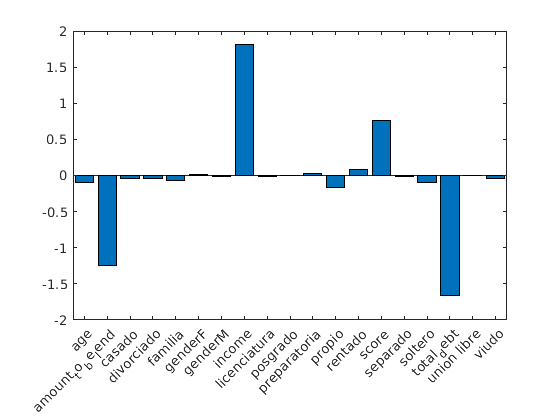

ygraph=Wperceptron.m4g2(2:20);
xgraph=categorical({'income' 'age' 'score' 'total_debt' 'amount_to_be_lend' 'genderF' 'genderM' 'familia' 'propio' 'rentado'  'licenciatura' 'posgrado' 'preparatoria' 'casado' 'divorciado' 'separado' 'soltero' 'union libre' 'viudo'});
bar(xgraph,ygraph)

En este caso se grafica únicamente el peso de las variables en grado 1 (sin el 'bias') para la cuarta selección de datos (todos los datos cuantitativos y cualitativos) ajustada a un modelo de grado 2. Se puede apreciar que dentro de las variables más importantes se encuentran en orden de importancia: Ingresos, Total de la deuda, Cantidad de dinero solicitada y Score. Ademas de estas 4 se puede encontrar que la variable edad contribuye un poco al modelo, a mayor edad, menor probabilidad de prestamo. Mismo caso con las personas que viven en casa propia, el solo hecho de tener casa propia implica una menor probabilidad de prestamo. Por otra parte, se tiene mayor probabilidad de recibir un prestamo por el solo hecho de vivir en una casa rentada. Importante notar que estas ultimas 3 variables son 'complementarias' es decir, ayudan a mejorar el modelo, no obstante, no son determinantes como lo son las primeras 4 variables mencionadas. 

## Desempeño de los modelos

A continuación se muestra el desempeño de los modelos ajustados. las claves m1g1 representan el modelo1 en grado1.

- La primer columna se refiere a la exactitud; cantidad de aciertos entre la cantidad de datos. 

- La segunda columna se refiere a la precisión; Predichos positivos acertados / (Verdaderos positivos)

- La tercer columna se refiere al recall; Predichos positivos acertados / (Predichos positivos)

Lo que se busca en estas métricas es que se acerquen lo mayor posible a 1. A partir de 0.6 se puede considerar un buen modelo debido a que se encuentran tendencias. 

Importante resaltar que cuando se utilizan modelos con datos cuantitativos se encuentran tendencias interesantes, mientras que utilizando modelos con datos cualitativos no se encuentra mucha información relevante. Cuando se hace un modelo de los datos cuantitativos y se le añade la información de los datos cualitativos el modelo presenta mejore métricas que cuando se utilizaba únicamente los datos cuantitativos. Por lo tanto, se puede concluir que los datos cualitativos por si solos no son buenos para hacer predicción ni clasificación, sin embargo, sirven para mejorar el modelo cuantitativo. 

Desempenio

Desempenio = struct with fields:
    m1g1: [0.6882 0.7394 0.6587]
    m2g1: [0.5771 0.3808 0.6000]
    m3g1: [0.6926 0.7283 0.6673]
    m4g1: [0.6936 0.7372 0.6660]
    m1g2: [0.7033 0.7728 0.6673]
    m2g2: [0.6052 0.5367 0.6040]
    m3g2: [0.7141 0.7528 0.6870]
    m4g2: [0.7627 0.7884 0.7390]


## Estimados (Predicciones)

Para cada uno de los datos se tomará un 'concenso' entre todos los modelos para observar cuantos de los modelos sugieren que la  persona merece ser aprobada o no merece ser aprobada. Mientras más modelos sugieren su aprobación mayor será la probabilidad de que este sea realmente aprobado. Mismo caso con las negativas, mientras más modelos sugieran que no se le debe prestar a la persona, mayor será la probabilidad de que realmente no se le deba prestar a la persona. 

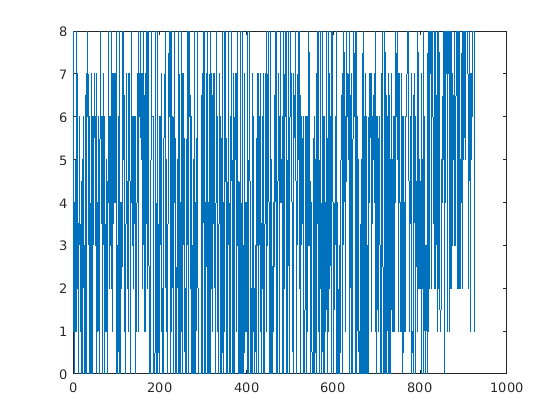

YgGlobal = zeros(size(Y));
for k=1:2
    for i=1:4
        eval(sprintf('YgGlobal = YgGlobal + Yg.m%dg%d;',i,k));
    end
end
plot(YgGlobal)

## Porcentaje de aciertos en 1's y 0's para predicciones comunes entre los modelos

zeros_ = zeros(9,1);
ones_ = zeros(9,1);
YgG = YgGlobal

YgG =      1
     8
     0
     1
     1
     3
     7
     1
     8
     2


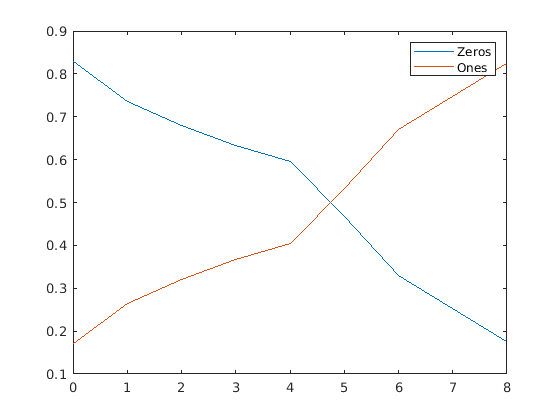

for i=1:9
    tmp00 = sum(~(YgG(YgG==i-1)==i-1)-Y(YgG==i-1));
    tmp01 = sum((YgG(YgG==i-1)==i-1));
    zeros_(i) = 1 + tmp00/tmp01; % 1 - error en los predichos 
    
    tmp10 = sum((YgG(YgG==i-1)==i-1)-Y(YgG==i-1));
    tmp11 = sum(YgG(YgG==i-1)==i-1);
    ones_(i) = 1- tmp10/tmp11; % 1 - error en los predichos 
end
plot(0:8,zeros_)
hold on
plot(0:8,ones_)
hold off
legend('Zeros','Ones')

Podemos observar que si la mayoría de los modelos sugieren que se le debe rechazar el prestamo a la persona (linea azul) existe una probabilidad cercana al 83% de que la predicción resulte cierta. Por otra parte, si se consideran los 8 modelos para una predicción en la cual se le preste a la persona, se puede lograr una tasa de aciertos cercana al 82%. En ambos casos el resultado tuvo mejores efectos que cualquiera de los modelos por separado. El problema de utilizar este mecanismo es que se limita la cantidad de usuarios a los que se puede clasificar con 8 modelos con respuesta afirmativa o negativa de manera conjunta. 

Para disminuir el impacto de la cantidad de usuarios que se pueden pronosticar, se utiliza un concenso acumulativo, en el cual se presentan las sumas de los modelos y sus predicciones. 

## Porcentaje de aciertos acumulativos en 1's y 0's para predicciones comunes entre los modelos

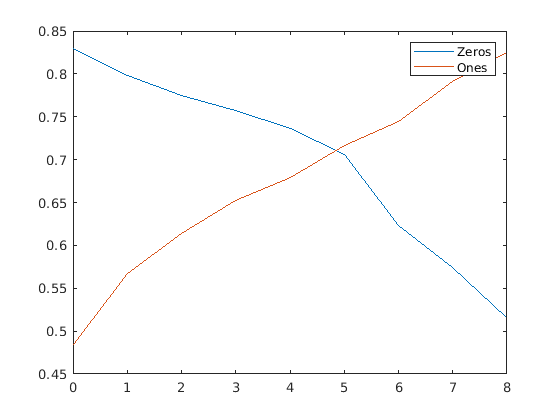

zeros_ = zeros(9,1);
ones_ = zeros(9,1);
for i=1:9
    tmp00 = sum(~(YgG(YgG<i)<i)-Y(YgG<i));
    tmp01 = sum((YgG(YgG<i)<i));
    zeros_(i) = 1 + tmp00/tmp01; % 1 - error en los predichos 
    
    tmp10 = sum((YgG(YgG>=i-1)>=i-1)-Y(YgG>=i-1));
    tmp11 = sum(YgG(YgG>=i-1)>=i-1);
    ones_(i) = 1- tmp10/tmp11; % 1 - error en los predichos 
end
plot(0:8,zeros_)
hold on
plot(0:8,ones_)
hold off
legend('Zeros','Ones')

En este caso, la probabilidad de acertar una respuesta negativa (linea azul) aceptando que los 8 modelos sugieran lo mismo es cercana al 83%, si 7 o mas modelos sugieren la respuesta negativa se logra una tasa de aciertos del 80%, si 6 o más modelos sugieren la negativa se logra una tasa cercana al 77%. Del mismo modo, si los 8 modelos sugieren una respuesta positiva se logra una tasa de aciertos cercana al 83%, si 7 o más modelos sugieren la positiva se logra una tasa cercana al 80%. 

Si para este tipo de ejercicios se preferirá aceptar únicamente a aquellos de los que estemos mayormente seguros de tener una respuesta postiva, entonces se preferirá tener un concenso de 8,7 o 6 modelos, según el riesgo que se desee correr. 

## Clasificación de usuarios aceptados.

nneuronas

nneuronas =      5    10    15    25    40    65   105


FuncCosto

FuncCosto = struct with fields:
    m1: [1.3000 1.0570 1.1136 1.5190 1.8541 1.8305 1.5481]
    m2: [2.6068 1.8197 1.5247 2.1311 1.6380 2.1911 2.7377]
    m3: [2.4051 2.0441 1.7341 1.9392 2.3083 2.2195 2.9159]
    m4: [3.3119 2.8754 2.4257 2.9509 3.0315 3.6213 3.8891]


En este caso se muestran las calificaciones obtenidas en la función de costo de redes competitivas. El objetivo en redes competitivas es minimizar la función de costo. Se analizarán algunas de las clasificaciones del modelo 1 (con 10 clusters propuestos inicialmente), así como las clasificaciones del modelo 4 (con 15 clusters propuestos inicialmente)

mean([income age score total_debt amount_to_be_lend],1)

ans = 	1.0e+04 *

    2.3398    0.0033    0.0669    4.8371    4.0563


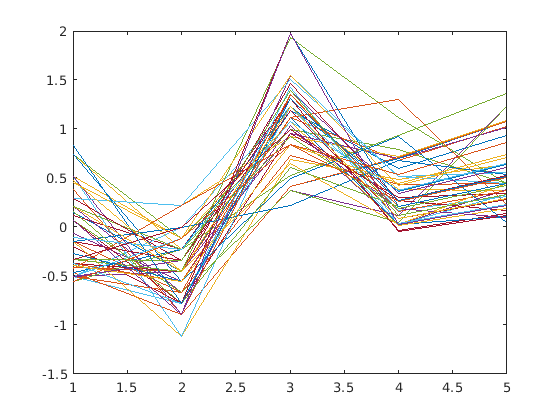


Yg_ = vec2ind(Red.m1.n10(X.m1g1'));
Un = unique(Yg_);
plot(X.m1g1(Yg_==Un(1),2:end)')

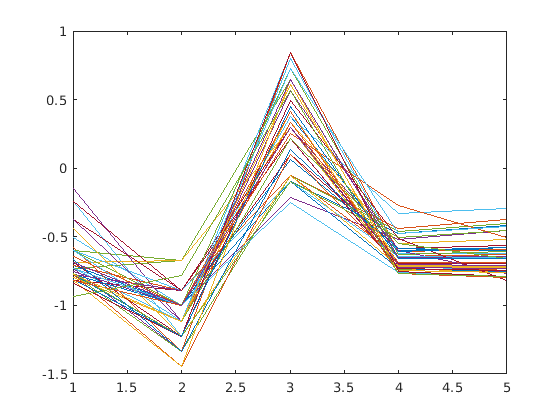


plot(X.m1g1(Yg_==Un(2),2:end)')

Jovenes con muy buen score, ingresos menores al promedio. 

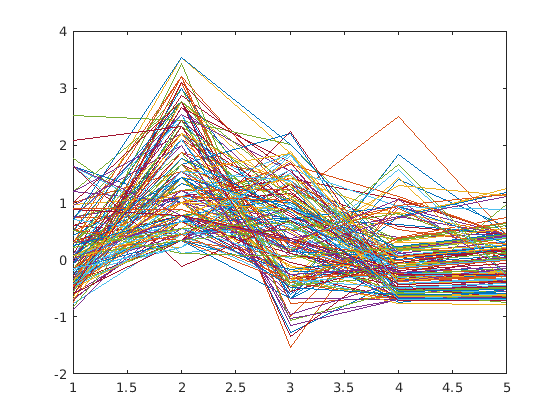

plot(X.m1g1(Yg_==Un(3),2:end)')

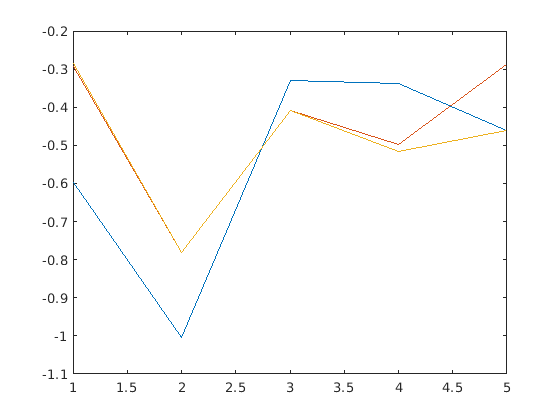


plot(X.m1g1(Yg_==Un(4),2:end)')

2 casos anormales en los que los usuarios se presentan desde 0.3 hasta 1 desviaciones estandar abajo del promedio en todas las variables. 

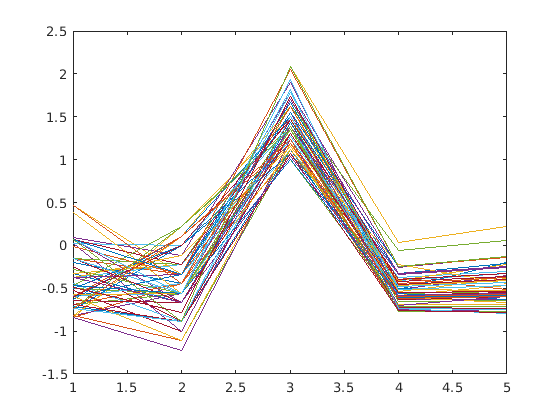

plot(X.m1g1(Yg_==Un(5),2:end)')

Personas con un score excepcionalmente bueno. 

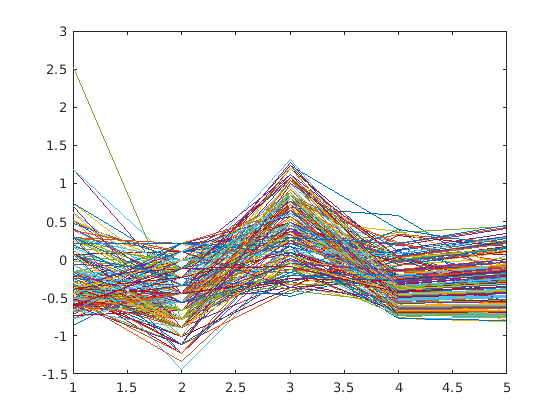

plot(X.m1g1(Yg_==Un(6),2:end)')

Personas jovenes con ingresos promedio, buen score y deudas pequeñas que quieren refinanciar el 100% de la deuda. 

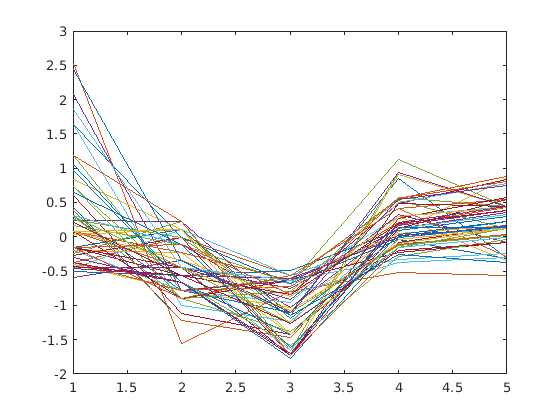

plot(X.m1g1(Yg_==Un(7),2:end)')

Personas con Score bajo, pero con ingresos más altos que los de la media. deuda y credito similar al del resto de la población. 

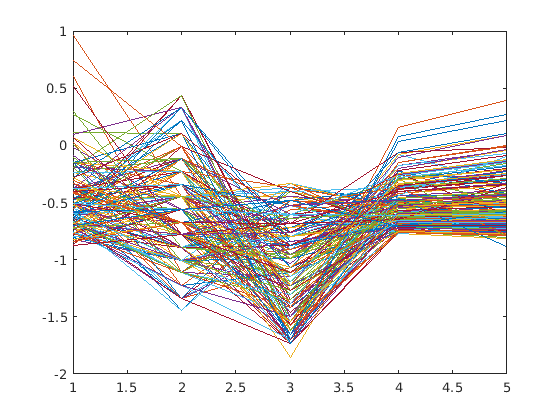

plot(X.m1g1(Yg_==Un(8),2:end)')

Gente con distintas cualidades en score y edad, pero que piden casi exactamente lo mismo que lo que deben. 

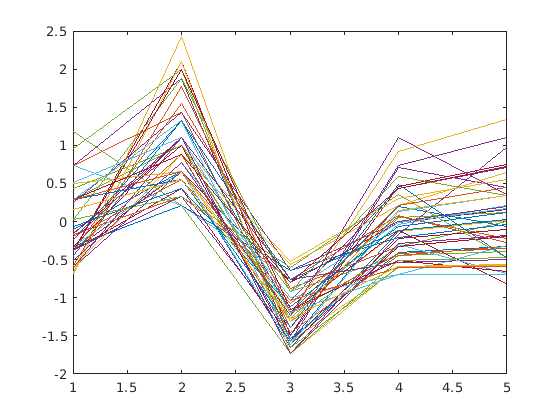

plot(X.m1g1(Yg_==Un(9),2:end)')

Personas con edad mayor a la media, score bajo, ingresos promedio y piden la misma cantidad que la gente promedio.

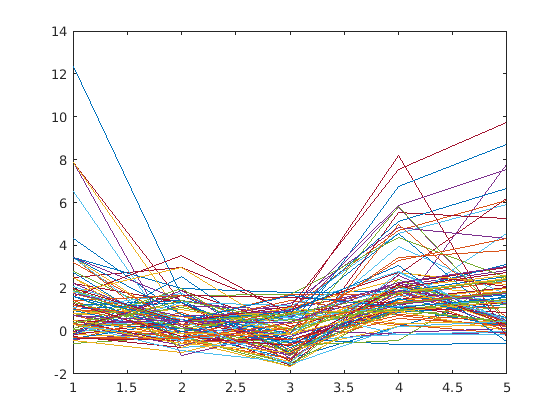

plot(X.m1g1(Yg_==Un(10),2:end)')

Usuarios con ingresos demasiado altos en comparación con la media, score medio a bueno, deudas grandes, prestamos grandes. 

## Modelo 4. Variables cuantitativas y cualitativas

Recordando el orden de las variables: 'income' 'age' 'score' 'total_debt' 'amount_to_be_lend' 'genderF' 'genderM' 'familia' 'propio' 'rentado'  'licenciatura' 'posgrado' 'preparatoria' 'casado' 'divorciado' 'separado' 'soltero' 'union libre' 'viudo'

La mayoría de las clasificaciones cuando se tienen variables cualitativas se ven sesgadas por este tipo de variables. Pareciera que la parte cuantitativa tiene muy poca importancia para la clasificación no supervisada de usuarios en este modelo. 

Como interpretar los graficos: la parte cuantitativa se interpreta de la misma forma en la que se presentó en el apartado anterior, la parte cualitativa cuando es menor a 0 se interpreta como una negativa a la variable, si es mayor a 0 se intepreta como una positiva a la variable. Es decir, si se presenta negativo en genderF y positivo en genderM se considera que la persona en cuestión es de genero másculino. Las variables pertenecientes a una misma categoría se presumen como mutuamente excluyentes, es decir, si una persona vive en una casa rentada no vivirá en una casa de su familian, ni en casa propia. En caso de que no se tenga un valor positivo en ninguna de las posibles categorías se tomará por supuesto que el usuario no presentó información suficiente en este campo. 

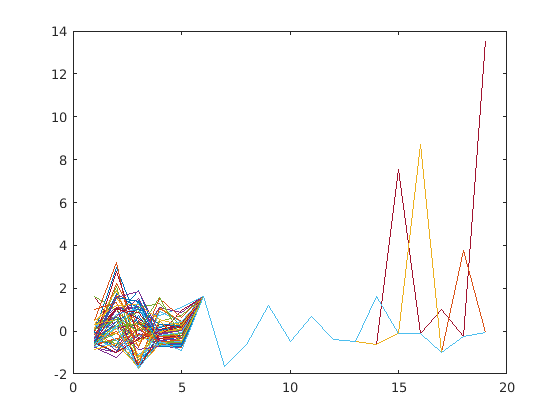


Yg_ = vec2ind(Red.m3.n15(X.m3g1'));
Un = unique(Yg_);

plot(X.m4g1(Yg_==Un(1),2:end)')

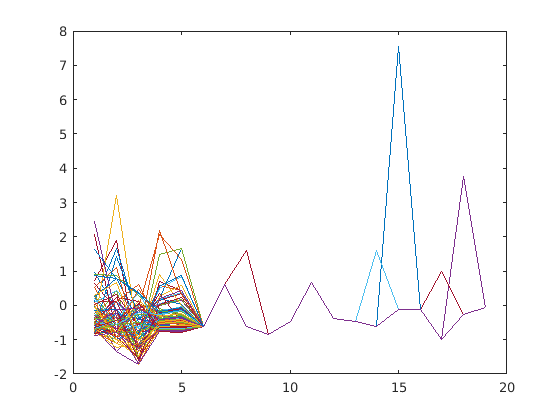


plot(X.m4g1(Yg_==Un(2),2:end)')

Hombre, vive con familia (o no presenta información al respecto), con licenciatura, no separado y no viudo. 

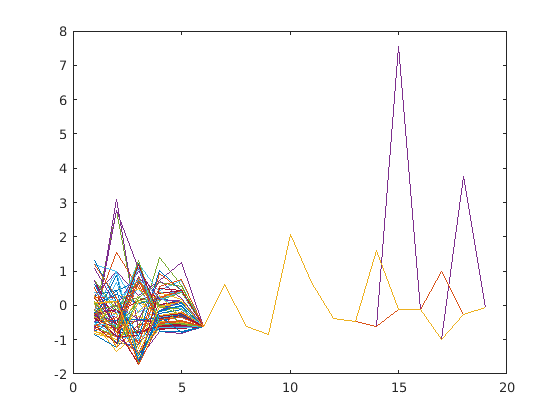

plot(X.m4g1(Yg_==Un(3),2:end)')

Hombre, casa rentada, con licenciatura, no separado y no viudo. 

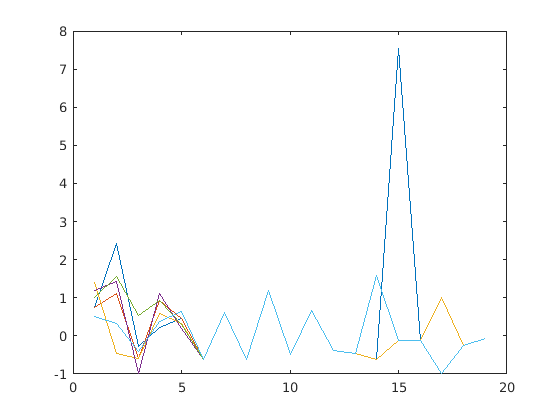

plot(X.m4g1(Yg_==Un(4),2:end)')

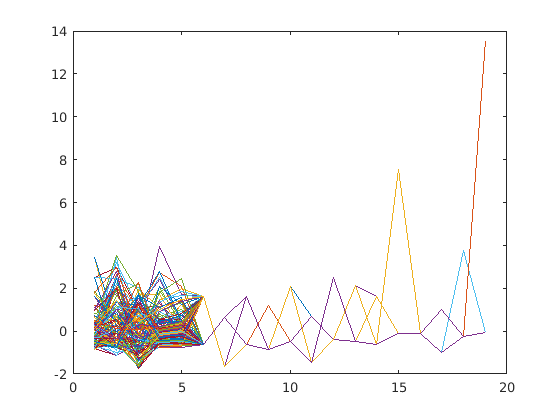


plot(X.m4g1(Yg_==Un(5),2:end)')

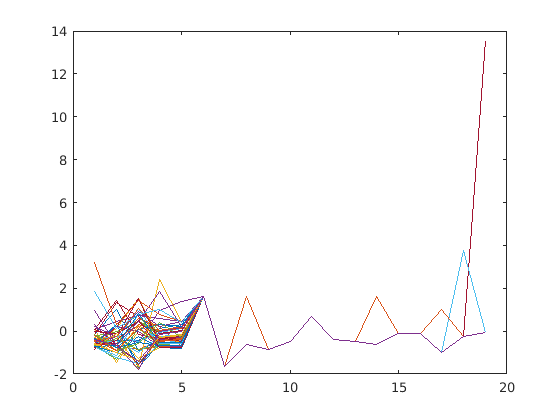


plot(X.m4g1(Yg_==Un(6),2:end)')

Mujer, vive con la familia (o no presenta información), con licenciatura, no viuda, no separada y no divoricada. 

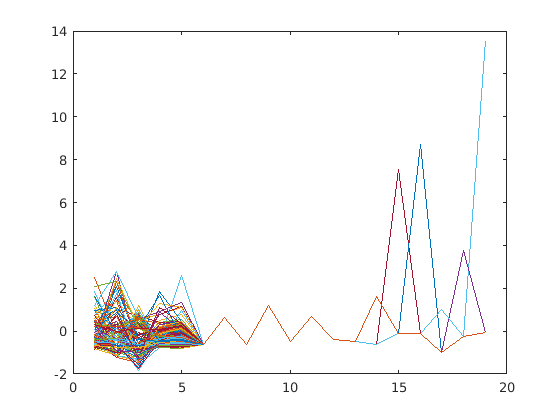

plot(X.m4g1(Yg_==Un(7),2:end)')

Hombre, casa propia, con licenciatura, no viudo. 

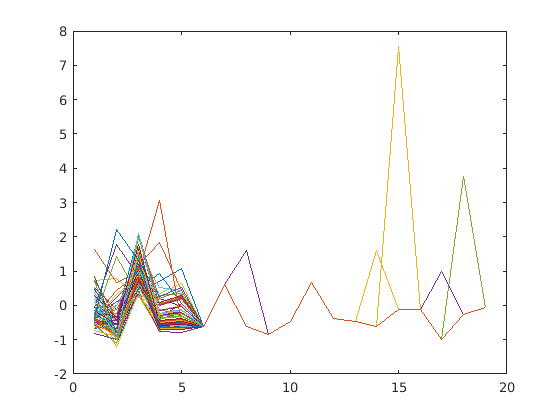

plot(X.m4g1(Yg_==Un(8),2:end)')

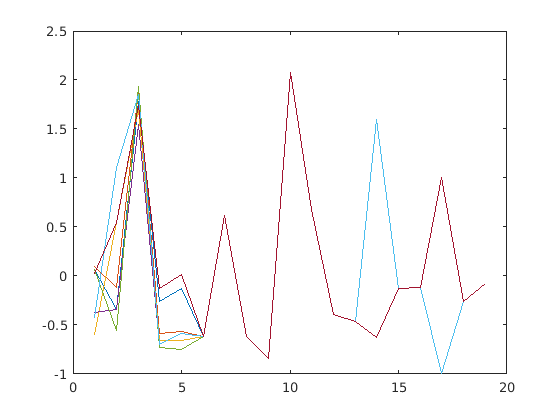


plot(X.m4g1(Yg_==Un(9),2:end)')

Hombre, casa rentada, licenciatura, no separado/ no divorciado/ no viudo y con muy buen score. 

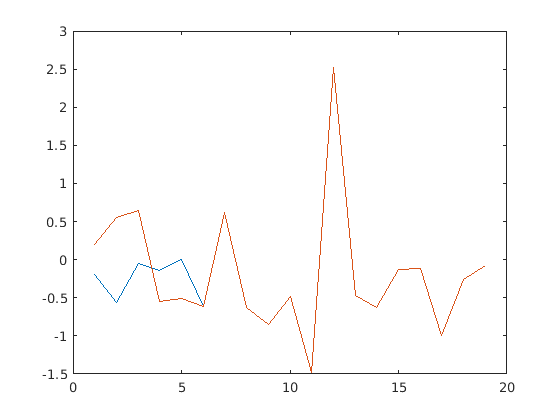

plot(X.m4g1(Yg_==Un(10),2:end)')

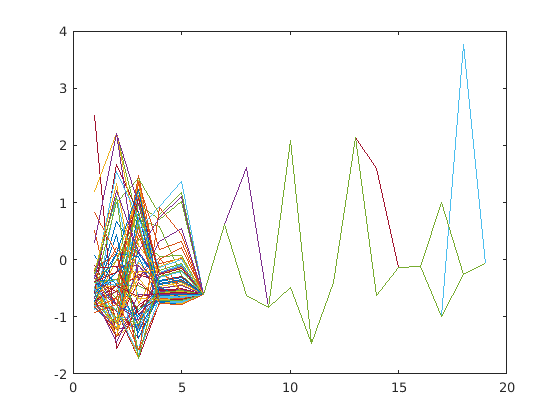


plot(X.m4g1(Yg_==Un(11),2:end)')

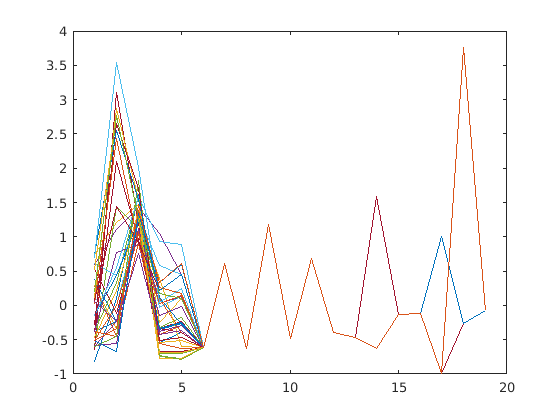


plot(X.m4g1(Yg_==Un(12),2:end)')

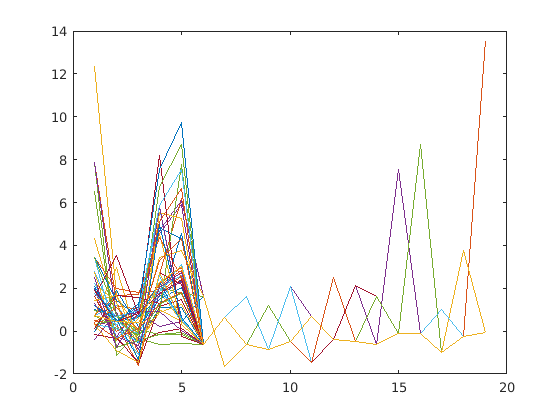


plot(X.m4g1(Yg_==Un(13),2:end)')

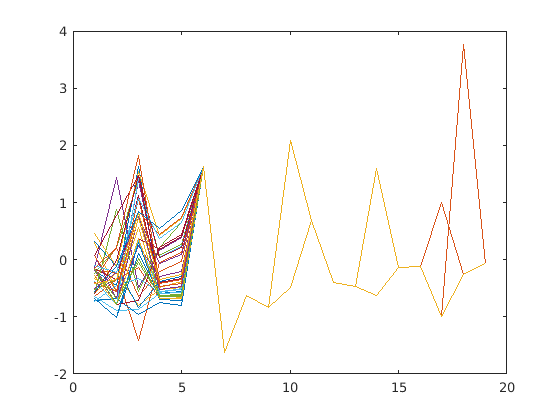


plot(X.m4g1(Yg_==Un(14),2:end)')

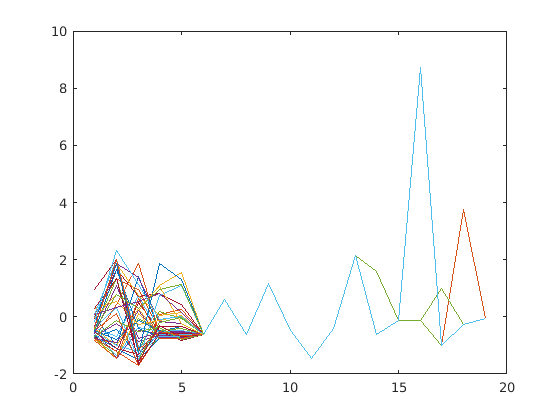


plot(X.m4g1(Yg_==Un(15),2:end)')

Hombre, casa propia, con doctorado, no divorciado y no viudo. 